# Systematic review of SysID - Different models and prediction error methods

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Jingxiao Liu
% Inferlab, CEE, CMU
% June, 2019
% Matlab live script for introducing different dynamic models and 
% prediction error methods for identifying them
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Part 3. Prediction error methods

## 3.1 Different model types

### 3.1.1 Finite impulse response (FIR) model


$$y\left(t\right)=b_1 u\left(t-1\right)+b_2 u\left(t-2\right)+\cdots +b_{n_b } \left(t-n_b \right)+e\left(t\right)=\left(\sum_{k=1}^{n_b } b_k q^{-k} \right)u\left(t\right)+e\left(t\right)=B\left(q\right)u\left(t\right)+e\left(t\right)$$


if $n_b$ is infinity, this is a infinite impulse response model

### 3.1.2 Autoregressive exogenous (ARX) model


$$\begin{array}{l}
y\left(t\right)+a_1 y\left(t-1\right)+\cdots +a_{n_a } y\left(t-n_a \right)=b_1 u\left(t-1\right)+b_2 u\left(t-2\right)+\cdots {+b}_{n_b } \left(t-n_b \right)+e\left(t\right)\\
\left(\sum_{k=0}^{n_a } a_k q^{-k} \right)y\left(t\right)=\left(\sum_{k=1}^{n_b } b_k q^{-k} \right)u\left(t\right)+e\left(t\right)\\
y\left(t\right)=\frac{B\left(q\right)}{A\left(q\right)}u\left(t\right)+\frac{1}{A\left(q\right)}e\left(t\right)
\end{array}$$


### 3.1.3 Autoregressive moving average exogenous (ARMAX) model (equation error model family)


$$\begin{array}{l}
y\left(t\right)+a_1 y\left(t-1\right)+\cdots +a_{n_a } y\left(t-n_a \right)=b_1 u\left(t-1\right)+b_2 u\left(t-2\right)+\cdots +b_{n_b } \left(t-n_b \right)+e\left(t\right)+c_1 e\left(t-1\right)+\cdots +c_{n_c } e\left(t-n_c \right)\\
\left(\sum_{k=0}^{n_a } a_k q^{-k} \right)y\left(t\right)=\left(\sum_{k=1}^{n_b } b_k q^{-k} \right)u\left(t\right)+\left(\sum_{k=0}^{n_c } c_k q^{-k} \right)e\left(t\right)\\
y\left(t\right)=\frac{B\left(q\right)}{A\left(q\right)}u\left(t\right)+\frac{C\left(q\right)}{A\left(q\right)}e\left(t\right)
\end{array}$$


### 3.1.4 Output-error model

If the linear difference equation is error-free, but that the noise consists of white measurement noise only:


$$\begin{array}{l}
x\left(t\right)+f_1 x\left(t-1\right)+\cdots +f_{n_f } x\left(t-n_a \right)=b_1 u\left(t-1\right)+b_2 u\left(t-2\right)+\cdots +b_{n_b } \left(t-n_b \right)\\
y\left(t\right)=x\left(t\right)+e\left(t\right)\\
y\left(t\right)=\frac{\left(\sum_{k=1}^{n_b } b_k q^{-k} \right)}{\left(\sum_{k=0}^{n_f } f_k q^{-k} \right)}u\left(t\right)+e\left(t\right)\\
y\left(t\right)=\frac{B\left(q\right)}{F\left(q\right)}u\left(t\right)+e\left(t\right)
\end{array}$$


### 3.1.5 Box-Jenkins model (contains above all)


$$y\left(t\right)=\frac{B\left(q\right)}{F\left(q\right)}u\left(t\right)+\frac{C\left(q\right)}{A\left(q\right)}e\left(t\right)$$


## 3.2 2-DoF mass-spring-damper system

Define stiffness and mass matrices

|\/\/\/\/\O\/\/\/\/\O

   k1 c1  m1  k2 c2  m2


$$M\ddot{X} +C\dot{X} +\textrm{KX}=F$$


clc;
clear;
close all;
addpath functions\
m1=5; %mass 1 [kg]
m2=2; %mass 2 [kg]
k1=200; %spring 1 [N/m]
k2=100; %spring 2 [N/m]
c1=10; % damping coeff 1
c2=10; % damping coeff 2
M=[m1 0;0 m2]; %mass matrix
K=[k1+k2 -k2; -k2 k2]; %stiffness matrix
Damp=[c1+c2 -c2; -c2 c2]; % damping matrix
T = 10; %length of time duration
nt = 500; %number of time stamps
Fs = nt/T;
tspan=linspace(0,T,nt);
F = zeros(2,length(tspan)); %input force
F(1,:) = 20*sin(10*tspan);

### 3.2.1 Load the data generated in script 1

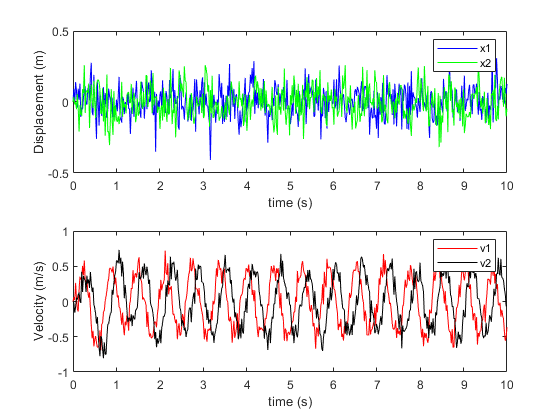

ysol = csvread(['data\2dof_noP.csv']); %load data
T = 10; %length of time duration
nt = 500; %number of time stamps
tspan=linspace(0,T,nt);
figure(1)
plot_dv(tspan,ysol')

### 3.2.2 FIR model identification


$${\left\lbrack y\left(n_b \right),\cdots ,y\left(N\right)\right\rbrack }^T =\left\lbrack \begin{array}{cccc}
u\left(n_b -1\right) & u\left(n_b -2\right) & \cdots  & u\left(0\right)\\
u\left(n_b \right) & u\left(n_b -1\right) & \cdots  & u\left(1\right)\\
\vdots  & \vdots  & \; & \vdots \\
u\left(N_1 \right) & u\left(N-2\right) & \cdots  & u\left(N-n_b \right)
\end{array}\right\rbrack \left\lbrack b_1 ,b_2 ,\cdots ,b_{n_b } \right\rbrack T$$


### 3.2.3 ARX model identification


$${\left\lbrack y\left(\mathrm{max}\left(n_a ,n_b \right)\right),\cdots ,y\left(N\right)\right\rbrack }^T =\left\lbrack \begin{array}{cccccc}
-y\left(n_a -1\right) & \cdots  & -y\left(0\right) & u\left(n_a -1\right) & \cdots  & u\left(n_a -n_b \right)\\
-y\left(n_a \right) & \cdots  & -y\left(1\right) & u\left(n_a \right) & \cdots  & u\left(n_a -n_b +1\right)\\
\vdots  & \; & \vdots  & \vdots  & \; & \vdots \\
-y\left(N-1\right) & \cdots  & -y\left(N-n_a \right) & u\left(N-1\right) & \cdots  & u\left(N-n_b \right)
\end{array}\right\rbrack \left\lbrack a_1 ,a_2 ,\cdots ,a_{n_a } ,b_1 ,b_2 ,\cdots ,b_{n_b } \right\rbrack T$$


### 3.2.4 ARMAX model identification


$${\left\lbrack y\left(\max \left(n_a ,n_b ,n_c \right)\right),\cdots ,y\left(N\right)\right\rbrack }^T =\left\lbrack \begin{array}{ccccccccc}
-y\left(n_a -1\right) & \cdots  & -y\left(0\right) & u\left(n_a -1\right) & \cdots  & u\left(n_a -n_b \right) & \epsilon \left(n_a -1\right) & \cdots  & \epsilon \left(n_a -n_c \right)\\
-y\left(n_a \right) & \cdots  & -y\left(1\right) & u\left(n_a \right) & \cdots  & u\left(n_a -n_b +1\right) & \epsilon \left(n_a \right) & \cdots  & \epsilon \left(n_a -n_c +1\right)\\
\vdots  & \; & \vdots  & \vdots  & \; & \vdots  & \vdots  & \; & \vdots \\
-y\left(N-1\right) & \cdots  & -y\left(N-n_a \right) & u\left(N-1\right) & \cdots  & u\left(N-n_b \right) & \epsilon \left(N-1\right) & \cdots  & \epsilon \left(N-n_c \right)
\end{array}\right\rbrack \left\lbrack a_1 ,a_2 ,\cdots ,a_{n_a } ,b_1 ,b_2 ,\cdots ,b_{n_b } ,c_1 ,c_2 \right\rbrack T$$


Need iterative solution

### 3.2.5 Output error identification

Similar to ARMAX, but error does not shift.

## 3.3 Prediction error method

All above can be generalizaed by considering the equation and out errors as prediction errors.

rng(94)
x0 = [0;0;0;0];
C = [1,0,0,0;
     0,1,0,0;
     0,0,1,0;
     0,0,0,1]; %observation matrix
params_ini = [1,1,100,100,5,5];
options = optimset('TolFun',10e-10);
params = zeros(5,6);
filenames = {'data\2dof_noP.csv','data\2dof_P6.csv','data\2dof_P5.csv','data\2dof_P4.csv','data\2dof_P3.csv'};
for i=1:5
    ysol = csvread(filenames{i});
    pe = @(params)pe_func(params,tspan,x0,C,F,ysol);
    params(i,:) = fmincon(pe,params_ini,[],[],[],[],[0,0,0,0,0,0],...
                            [],[],options);
end


Solver stopped prematurely.

fmincon stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 3000 (the default value).


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the default value of the step size tolerance and constraints are 
satisfied to within the d

True parameters:

disp([m1,m2,k1,k2,c1,c2])

     5     2   200   100    10    10



Estimated parameters

disp(params)

    5.0958    1.9714  210.3577   88.7253    8.5900   10.9539
    4.8999    1.7862  190.9814   79.6604   13.8270    9.2064
    5.3079    1.5864  220.3351   72.5978   14.4934    8.0642
    3.3300    0.0107    0.0197    0.6891   44.2831    0.0490
   10.3415    7.1056  113.9680  488.4342    0.0199    4.3962



Provide more domain knowledge

params_dk = zeros(5,6);
for i=1:5
    ysol = csvread(filenames{i});
    pe = @(params)pe_func(params,tspan,x0,C,F,ysol);
    params_dk(i,:) = fmincon(pe,params_ini,[],[],[],[],[0,0,0,0,0,0],...
                            [10,10,300,300,20,20],[],options);
end


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the default value of the step size tolerance and constraints are 
satisfied to within the default value of the constraint tolerance.

<stopping criteria details>




Estimated parameters

disp(params_dk)

    5.1482    1.9467  209.4788   90.6677    8.9435   11.1234
    5.1400    1.7829  200.1305   82.9822   13.4305    8.1667
    5.4153    1.8195  232.2843   83.0516   12.2736    9.1744
    5.2501    1.5224   76.2924  116.7385   19.4765    8.7539
    5.1163    5.7065  127.8472  293.1659    0.0657    8.4218

